imset = MyImageSet('.\data');

a=imset.read(1);
b=imset.read(3);
adisp = imset.read(2);
bdisp = imset.read(4);
zad = 256*ones(size(adisp))./double(adisp);
zbd = 256*ones(size(bdisp))./double(bdisp);

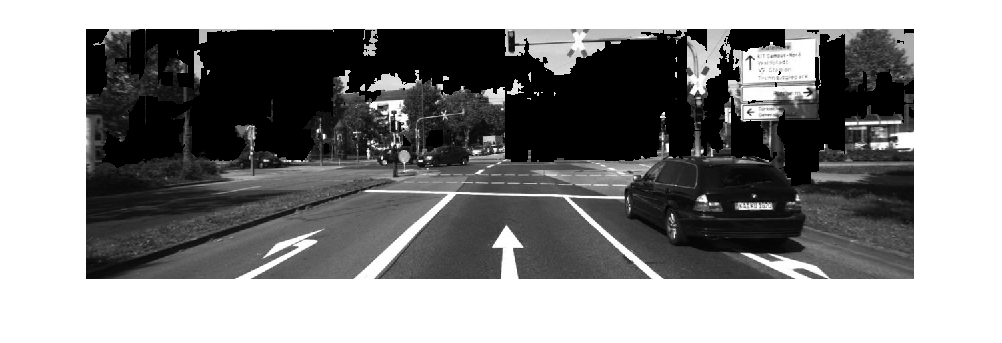

zamask = zad>(quantile(zad(1:100:end,:),0.65));
zbmask = zbd>(quantile(zbd(1:100:end,:),0.65));
a2 = rgb2gray(a);
a2(zamask)=0;
b2 = rgb2gray(b);
b2(zbmask)=0;
imshow(a2);

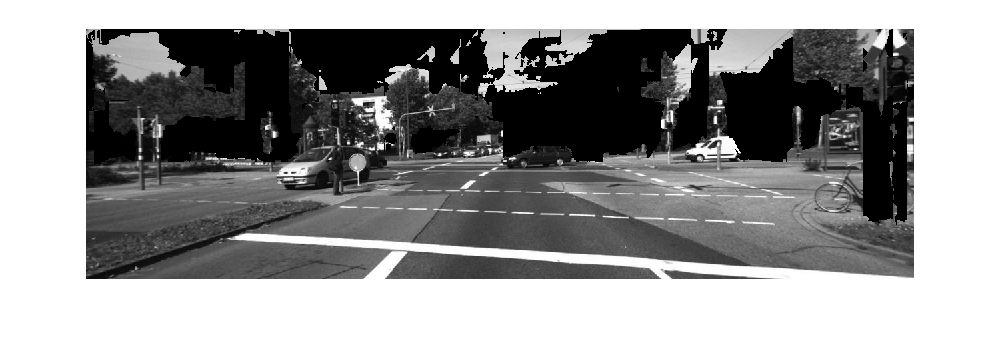

imshow(b2);

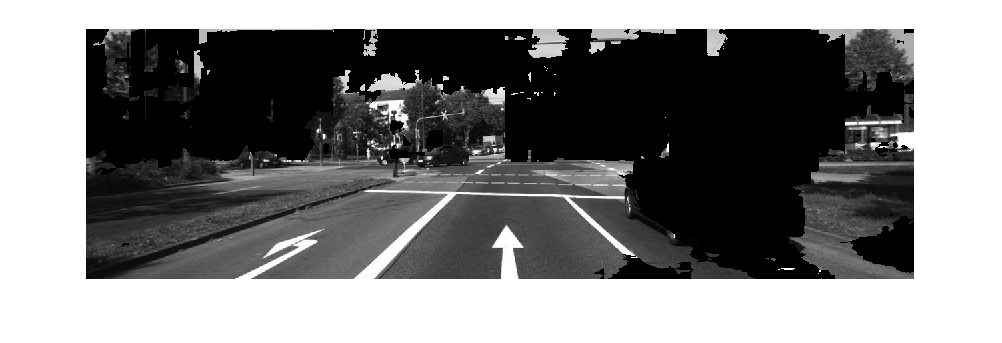

zamask2 = zad<quantile(zad, 0.2,2);
zbmask2 = zbd<quantile(zbd,0.2,2);
a2(zamask2)=0;
b2(zbmask2)=0;
imshow(a2);

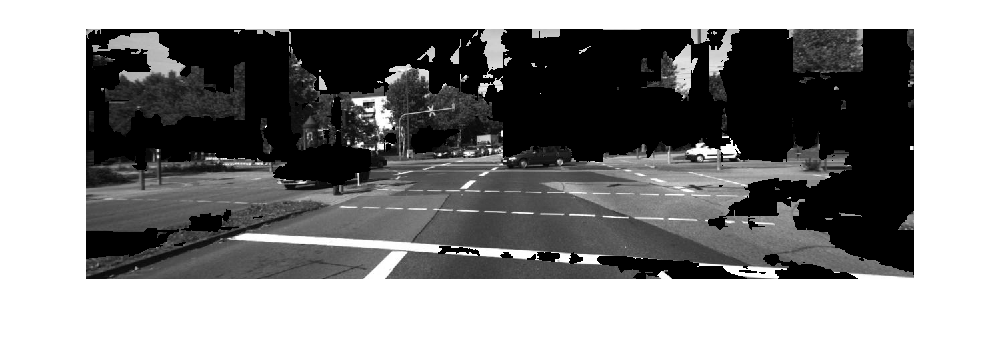

imshow(b2);

a_corners=detectFASTFeatures(rgb2gray(a));
a_mineig = detectMinEigenFeatures(rgb2gray(a));
a_brisk = detectBRISKFeatures(rgb2gray(a));
imshow(a); hold on;

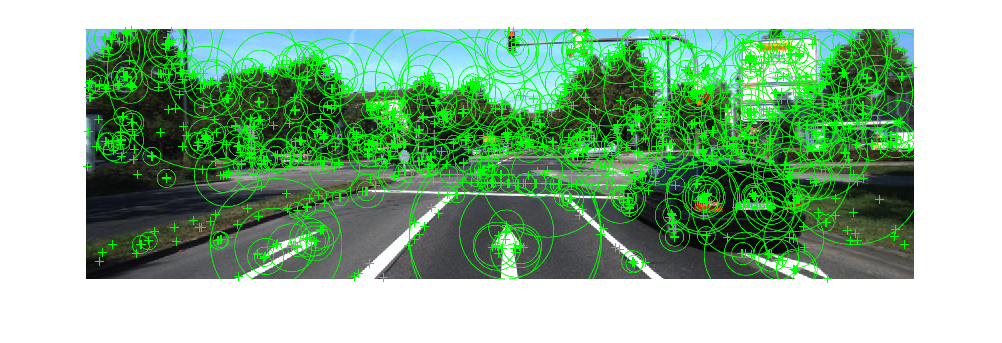

plot(a_corners.selectUniform(500,size(a)));
plot(a_mineig.selectUniform(500,size(a)));
plot(a_brisk.selectUniform(500,size(a)));
hold off;

v=randsample(1:size(a,1),30000,true);
w=randsample(1:size(a,2),30000,true);
%v = v(1:length(w));
xx=[a_brisk.selectUniform(1000,size(a)).Location;
    a_corners.selectUniform(500,size(a)).Location;
    a_corners.selectUniform(500,size(a)).Location;
   [w;v]'
];
i=sub2ind(size(a), round(xx(:,2)), round(xx(:,1)));
 ar=a(:,:,1);
 ab=a(:,:,2);
 ag=a(:,:,3);
pcl = pointCloud([xx,2000*zad(sub2ind(size(zad), round(xx(:,2)), round(xx(:,1))))],...
    'Color', [ar(i),ag(i),ab(i)] );
pcl = pcdenoise(pcl);

v=randsample(1:size(a,1),30000,true);
w=randsample(1:size(a,2),30000,true);
xx=[w;v]';

 ar=a(:,:,1);
 ab=a(:,:,2);
 ag=a(:,:,3);
 sub2ind(size(a), round(xx(:,2)), round(xx(:,1)));
 i=sub2ind(size(a), round(xx(:,2)), round(xx(:,1)));
 ar=a(:,:,1);
 ab=a(:,:,2);
 ag=a(:,:,3);
pcl = pointCloud([xx,2000*zad(sub2ind(size(zad), round(xx(:,2)), round(xx(:,1))))],...
    'Color', [ar(i),ag(i),ab(i)] );
i=sub2ind(size(b), round(xx(:,2)), round(xx(:,1)));
 ar=b(:,:,1);
 ab=b(:,:,2);
 ag=b(:,:,3);
pcl2 = pointCloud([xx,2000*zad(sub2ind(size(zad), round(xx(:,2)), round(xx(:,1))))],...
    'Color', [ar(i),ag(i),ab(i)] );

gridSize = 0.1;
fixed = pcdownsample(pcl, 'gridAverage', gridSize);
moving = pcdownsample(pcl2, 'gridAverage', gridSize);
tform = pcregrigid(moving, fixed, 'Metric','pointToPlane','Extrapolate', true);

pcl2 = pctransform(pcl2,tform);
pclx = pcmerge(pcl,pcl2, 0.015);
pclx = pcdenoise(pclx, 'Threshold',0.01, 'NumNeighbors',2);

b_corners=detectFASTFeatures(rgb2gray(b));
imshow(b); hold on;

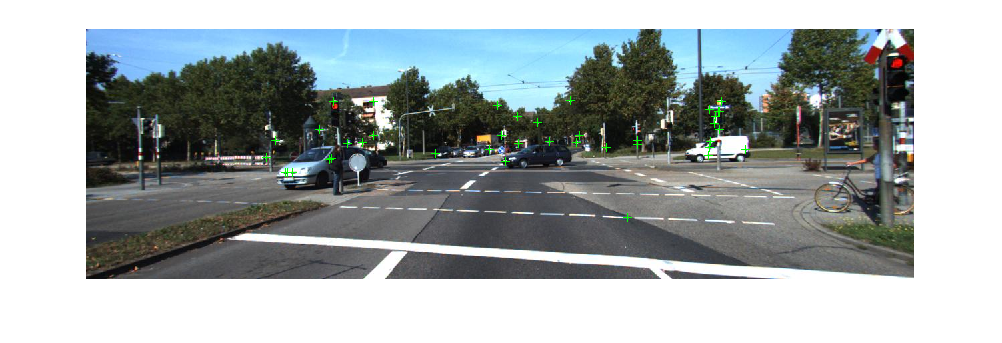

plot(b_corners.selectStrongest(40));
hold off;

We've extracted corners in each, but these corners on their own cannot be matched with eachother since there are no matchable descriptors. 

We have to efficiently estimate transformation based on the spatial relation between the two lists of points. 

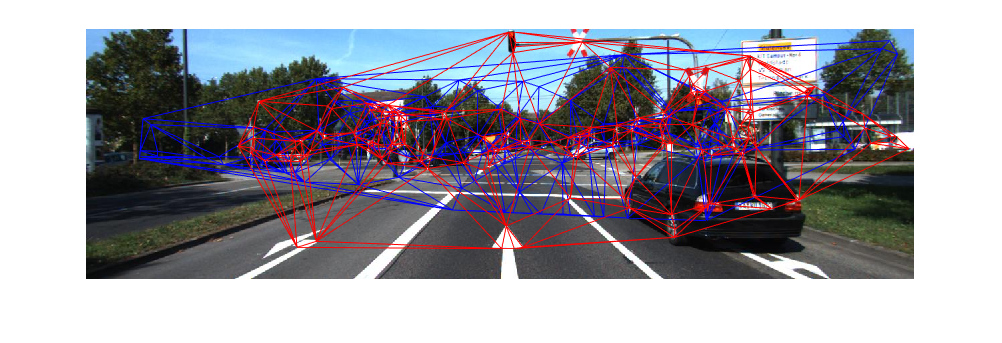

b_selected = b_corners.selectStrongest(200);
b_tri = delaunayTriangulation(double(b_selected.Location));
a_selected = a_corners.selectStrongest(200);
a_tri = delaunayTriangulation(double(a_selected.Location));
triplot(b_tri); hold on;
triplot(a_tri, 'color', 'red'); hold off;

One idea is to randomly pick pairs of 3 points close to eachother that are not colinear. Also, we need asymetry so it can be oriented. Do this in both images. Then we can match between these triangles.

Actually, since we are trying to match background and there is no reason to work with skewed cameras, we don't need rotational invariance. 

[za, zsa] = sampleTriangles(a_tri);

sampInd =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


[zb, zsb] = sampleTriangles(b_tri);

sampInd =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


%zsa is m x 3 matrix indexing into a_tri
%za is samething but with coordinates instead of index, m x 6
res=matchTriangles(za,zb);

res = res(:,:,1) =

    0.9430         0    0.8697    0.9600    0.4344         0    0.3698    0.9048    0.4348    0.8321    0.9048    1.2649         0         0    0.9255         0    0.0753   -0.2425    0.2457    0.9455         0    0.6644    0.9559    0.6644         0         0         0   -3.0087    0.3590         0    0.0817    0.3162    0.2104         0         0    0.2617    0.2834    0.9600    0.9806    0.9918    0.2352         0         0   -0.0708         0         0    0.5010         0    0.3542         0         0    0.8955    0.4407   -0.1491   -0.0370         0    1.1579         0         0         0    0.1597         0    0.5300    0.6210   -0.0767    2.0608         0    0.6295    0.9861   -0.1315    1.0000         0    0.2806         0   -0.1360   -0.4577    0.9062    0.2206         0         0    0.9104    0.8214    0.9191    0.8944    0.9638    0.7706    0.0288    0.9965    0.9345    0.6508   -0.1977    0.5494         0    0.8732    0.9339   -0.9761    0.9636         0

res = res(:,:,1) =

    0.4695   -1.1586   -0.8430    0.3556         0    0.4743    0.9048         0    0.4084    0.5496    0.8748   -0.0559    0.9916   -0.4930    0.9262    0.9345         0         0    0.1961         0         0         0    0.8815    0.4487         0         0    0.0352    0.8944         0    0.7433    0.3372         0    0.4856    0.9487    0.1293    0.9363         0    0.0650    0.9971    0.8000    0.2557    0.3358         0    0.1648    0.2630    0.9975   -0.1697   -0.3156    0.9990    0.9558    0.7493   -0.4472         0         0   -2.1213         0    0.1616    0.7223         0    0.0422         0    0.9990    0.6897    0.9990    0.5340    0.9231    0.8893    0.6423    0.2169    0.1159   -0.4427    0.0995         0    0.8051    0.5793    0.8051    0.8321    0.7255    0.8682    0.9551    0.5843    0.9767    0.8900    0.8743         0    0.9985         0   -0.0476    0.9701   -0.3665    0.4450    0.0438         0    0.8603         0    0.9956         0    0.9615

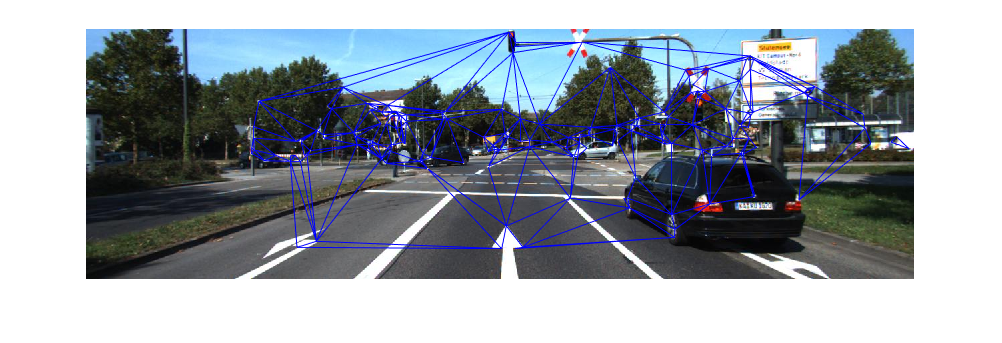

% res has coordinates from zsa to zsb now.
zma = zsa(res(:,1), :); 
% zma holds mx3 where each row indexes into a_tri.Points
zmb = zsb(res(:,2),:);
imshow(a); hold on;
triplot(zma, a_tri.Points(:,1), a_tri.Points(:,2));
hold off;

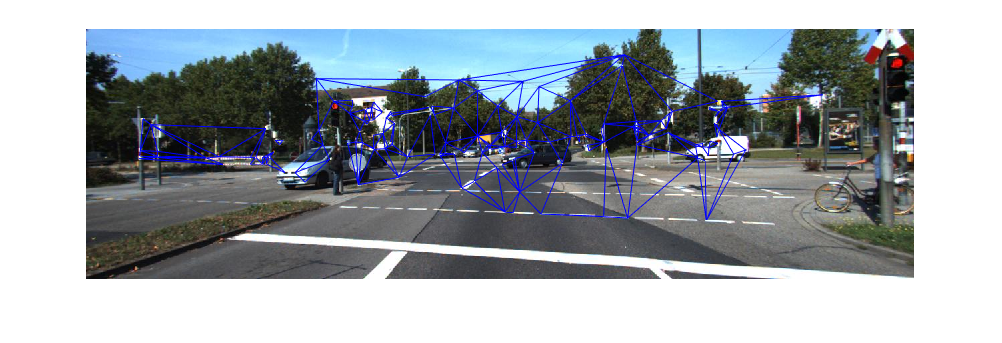

imshow(b); hold on;
triplot(zmb, b_tri.Points(:,1),b_tri.Points(:,2));
hold off;

%=za(res(:,1),:);
%zb=zb(res(:,2),:);
zaa = [a_tri.Points(zma(:,1),:) ; a_tri.Points(zma(:,2),:) ; a_tri.Points(zma(:,3),:)];
zbb = [b_tri.Points(zmb(:,1),:) ; b_tri.Points(zmb(:,2),:) ; b_tri.Points(zmb(:,3),:)];

sampInd=randsample(length(a_tri.ConnectivityList), 30);
connectedSample=a_tri.ConnectivityList(sampInd,:);
%convert this by mxn where each m is feature.
% row of source has 3 indices.

sample_triangle = a_tri.Points(reshape(connectedSample',...
    3*size(connectedSample,1),1), :);
res=getNormedTriangles(sample_triangle)

res = res(:,:,1) =

    0.7415         0         0         0    1.5364    0.0373    0.0753    0.7873    1.0403         0    0.1293    0.9998   -0.1800         0   -0.3401    0.7583    0.9958   -0.6788         0    0.2074         0         0   -0.4065    0.2873    1.0000    0.9420    0.7819   -0.7867    0.6035         0
   -0.2295    0.6653         0    0.2220    0.2305         0   -0.4327    0.6476    0.9977    0.3118         0    0.4745         0         0         0         0    0.1829         0    0.9516         0    0.9965   -0.0422         0   -0.4598    0.1080    0.1959    0.9593         0    0.7026    0.1282
         0    0.8609    0.9543    0.9989         0    0.9327         0         0         0   -0.2425    0.6251         0    0.9329    0.9637    0.3542    0.7982         0    0.7127    0.8869    0.9976    0.5260   -0.6051   -0.2772         0         0         0         0    0.9861         0   -0.1122


res(:,:,2) =

    0.6709         0    0.0345         0   -0.8963    0.5347 

res=permute(res, [2,1,3]);
res = reshape(res,[],6);

res =     0.7415   -0.2295         0    0.6709    0.8828         0
         0    0.6653    0.8609         0   -0.3718    0.5087
         0         0    0.9543    0.0345         0    0.2989
         0    0.2220    0.9989         0   -0.0793    0.0476
    1.5364    0.2305         0   -0.8963    0.9731         0
    0.0373         0    0.9327    0.5347         0    0.3606
    0.0753   -0.4327         0    0.9972    0.4704         0
    0.7873    0.6476         0    0.0762    0.7619         0
    1.0403    0.9977         0   -0.0085    0.0682         0
         0    0.3118   -0.2425         0   -0.1039    0.9701


matchFeatures()


sample_triangle=reshape(sample_triangle,[],1,2);
sample_triangle=permute(sample_triangle, [2,1,3]);

sample_triangle = sample_triangle(:,:,1) =

         787         732         745         613         681         701        1083        1083        1166         504         518         567         732         681         672         180         177         252         879         825         871         123         112          61         362         357         240         604         613         597         363         357         386         635         366         123         613         624         681        1083        1083        1166         518         542         567         738         681         741         240         160         142         879         939        1002         260         363         356         460         439         540         249         285         268         424         421         381         444         466         451         672         594         642         635         123          61         934         854         833        1002        

sample_triangle=reshape(sample_triangle, 3,[],2);

%make point closest to 0,0 the origin of each.
%arbitrary but let farthest point be v
%now make origin to v the base, and use length of this to normalize.

% o will have min manhattan, and all coords are in positive.
t = sample_triangle(:,:,1)+sample_triangle(:,:,2);
[~,oIndex]=min(t,[],1);
[~, vIndex]=max(t,[],1);
m=size(sample_triangle,1)*size(sample_triangle,2);
s=sub2ind(size(sample_triangle), oIndex,1:length(oIndex));
res = zeros([1,size(sample_triangle,2),2]);
res(:,:,1) = sample_triangle(s);
res(:,:,2) = sample_triangle(s+m);
normedTri = sample_triangle-res;
s=sub2ind(size(normedTri), vIndex,1:length(vIndex));
res(:,:,1) = normedTri(s);
res(:,:,2) = normedTri(s+m);
denom=sqrt(sum(res.*res,3));
normedTri=normedTri./denom;

imshow(a); hold on;

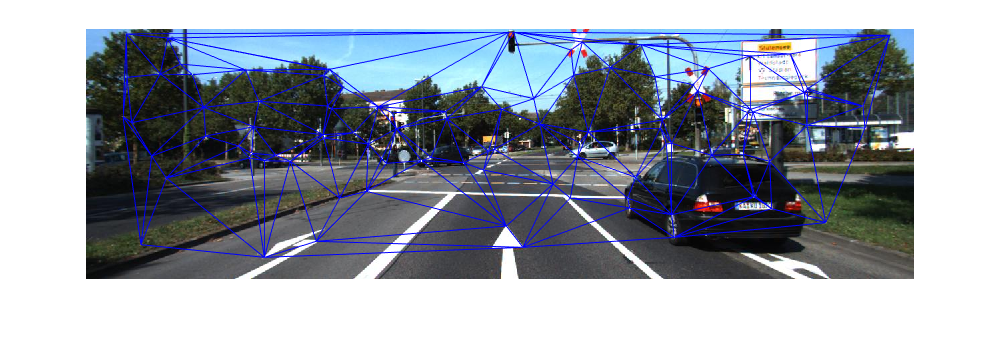

triplot(a_tri); hold off;

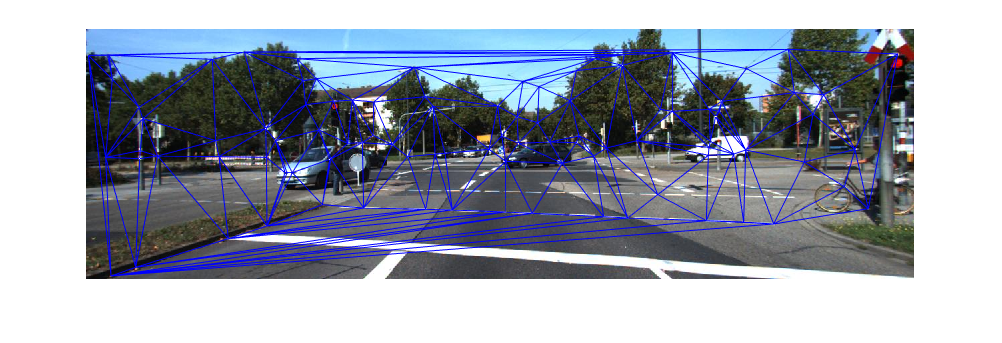

imshow(b); hold on;
triplot(b_tri); hold off;

function normedTri = getNormedTriangles(sample_triangle)    
sample_triangle=reshape(sample_triangle,[],1,2);
sample_triangle=permute(sample_triangle, [2,1,3]);
sample_triangle=reshape(sample_triangle, 3,[],2);
%make point closest to 0,0 the origin of each.
%arbitrary but let farthest point be v
%now make origin to v the base, and use length of this to normalize.

% o will have min manhattan, and all coords are in positive.
t = sample_triangle(:,:,1)+sample_triangle(:,:,2);
[~,oIndex]=min(t,[],1);
[~, vIndex]=max(t,[],1);
m=size(sample_triangle,1)*size(sample_triangle,2);
s=sub2ind(size(sample_triangle), oIndex,1:length(oIndex));
res = zeros([1,size(sample_triangle,2),2]);
res(:,:,1) = sample_triangle(s);
res(:,:,2) = sample_triangle(s+m);
normedTri = sample_triangle-res;
s=sub2ind(size(normedTri), vIndex,1:length(vIndex));
res(:,:,1) = normedTri(s);
res(:,:,2) = normedTri(s+m);
denom=sqrt(sum(res.*res,3));
normedTri=normedTri./denom;
end
function [res, connectedSample] = sampleTriangles(trii)
    sampInd=1:length(trii.ConnectivityList)%randsample(length(trii.ConnectivityList), floor(length(trii)/2));
connectedSample=trii.ConnectivityList(sampInd,:);
res = trii.Points(reshape(connectedSample',...
    3*size(connectedSample,1),1), :);
end
function [res,score] = matchTriangles(a,b)
    a=normTriangles(a);
    b=normTriangles(b);
    [res,score] = matchFeatures(a,b);
end
function res = normTriangles(trilist)
res=getNormedTriangles(trilist)
res=permute(res, [2,1,3]);
res = reshape(res,[],6);
end